# Apuntes de Clase - Intervalos de confianza, regresión lineal y dependencia de rango largo (LRD)

Herramientas Matemáticas para el Manejo de la Información

Sesión 13 - 7 de mayo de 2026

# Intervalos de Confianza

En vista de que los estimadores son variables aleatorias, es imposible determinar exactamente el parámetro de la población con una estimación puntual (es posible con probabilidad igual a cero). Además, la estimación puntual no aporta información con respecto a la precisión de la misma. Es por esto que se prefiere indicar un intervalo cuyo tamaño depende del tamaño de la muestra (y que podría, o no, incluir al parámetro que se desea estimar). A este intervalo se le llama **intervalo de confianza**.

## Estimador de la media para datos normalmente distribuidos

Si los valores de una muestra aleatoria están normalmente distribuidos:


$$X_i \sim \mathcal{N}\left( \mu_X,\sigma_X \right)$$


entonces, la variable aleatoria $\bar{X}$ se distribuye normal con parámetros $\mu_X$ y $\frac{\sigma_X}{\sqrt{n}}$:


$$\bar{X}  \sim \mathcal{N}\left(\mu_X,\frac{\sigma_X}{\sqrt{n}}\right)$$


y la variable aleatoria $Z$, se distribuye normal estándar:


$$Z =\frac{\bar{X}-\mu_X}{\frac{\sigma_X}{\sqrt{n}}} \sim \mathcal{N}(0,1)$$


## Observaciones

- El resultado presentado es consecuencia del teorema del límite central, para el caso particular de muestras normalmente distribuidas. Recuérdese que en dicha situación, no es necesario tener un tamaño infinito de la muestra.

- Cuando se realiza una estimación puntual de la media (por medio de la media muestral), de una muestra normalmente distribuida, los valores se distribuyen en todos los números reales. Esto significa, que lo único que podemos asegurar es que la media está en el intervalo $(-\infty,\infty)$.

- El anterior resultado es inútil para propósitos prácticos. Por esa razón se debe indicar un porcentaje de confianza menor al 100%, para reducir el tamaño del intervalo y disponer así de cotas finitas.

## Intervalo de confianza y su relación con el área bajo la curva

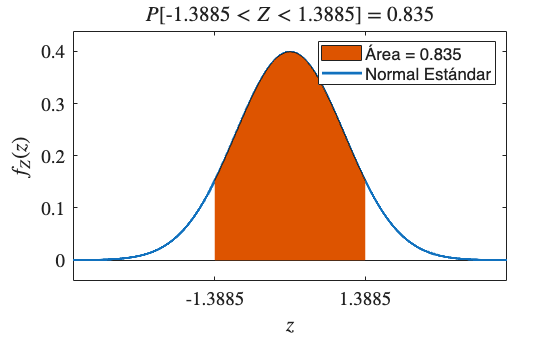

confianza = 0.835;
figure(1);
areanormalestandar(confianza);

## Intervalo de confianza para la media con varianza conocida

Si $\bar{X}$ es la media muestral de una muestra aleatoria de tamaño $n$, de una población normalmente distribuida, con varianza $\sigma_X^2$ finita; entonces, un intervalo de confianza del $100(1-\alpha)$% está dado por:


$$\bar{X}+z_{\alpha/2}\frac{\sigma_X}{\sqrt{n}}
< \mu <
\bar{X}-z_{\alpha/2}\frac{\sigma_X}{\sqrt{n}}$$


En donde $z_{\alpha/2}$ se obtiene con la inversa de la distribución acumulativa de $Z$. $z_{\alpha/2}=Q_Z\left(\frac{\alpha}{2}\right)$.

## Intervalo de confianza para la media con varianza desconocida

Si $\bar{X}$ es la media muestral de una muestra aleatoria de tamaño $n$ de una población normalmente distribuida, con varianza $\sigma_X^2$ finita y desconocida, un intervalo de confianza del $100(1-\alpha)$% está dado por:


$$\bar{X}+t_{\alpha/2}\frac{S}{\sqrt{n}}
< \mu <
\bar{X}-t_{\alpha/2}\frac{S}{\sqrt{n}}$$


En donde $t_{\alpha/2}$ se obtiene con la inversa de la distribución acumulativa de la distribución *t de Student* con $n-1$ grados de libertad.

## Función de densidad de probabilidad t de Student


$$T:\Omega \to \mathbb{R}$$



$$f_T(t;\nu) = \frac{\Gamma\left(\frac{\nu+1}{2}\right)} {\sqrt{\nu\pi}\,\Gamma\left(\frac{\nu}{2}\right)} \left(1+\frac{t^2}{\nu} \right)^{-\frac{\nu+1}{2}}$$


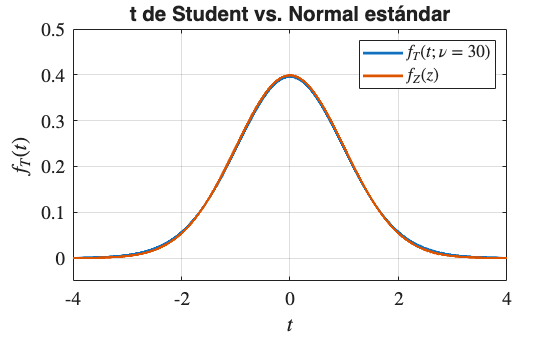

gradosdelibertad = 30;

t = linspace(-5,5,10000);
y = tpdf(t,gradosdelibertad);
figure(2);
superplot(t,y,'t de Student vs. Normal estándar',...
    '$t$','$f_T(t)$');
hold on;
z = normpdf(t,0,1);
superplot(t,z);
hold off;

axis([-4 4 -0.05 0.5]);

legend({['$f_T(t;\nu=',num2str(gradosdelibertad),')$',...
    ],...
    '$f_Z(z)$'},'Interpreter',"latex");

## Intervalo de confianza y su relación con la probabilidad (confianza)

Cuando se calcula un intervalo de confianza de una muestra aleatoria particular, se debe ser consciente de que el parámetro puede o no estar contenido en él. Por ejemplo, para el último caso estudiado, el intervalo de confianza es:


$$\left[\bar{X}+t_{\alpha/2}\frac{S}{\sqrt{n}}
,
\bar{X}-t_{\alpha/2}\frac{S}{\sqrt{n}}\right]$$


El tamaño del intervalo es: $-2t_{\alpha/2}\frac{S}{\sqrt{n}}$ y está centrado en $\bar{X}$. Dado que $\bar{X}$ puede tomar valores mayores o menores que $\mu_X$, es posible (con probabilidad $\alpha$) que el intervalo no contenga a $\mu_X$.

El porcentaje de confianza: el 95%, por ejemplo, sólo significa que el 95% de los intervalos calculados, de muestras aleatorias normalmente distribuidas, sí incluyen al párametro que se desea estimar.

n = 2;
confianza = 0.95;
alfa = 1-confianza;

p = 0;

for i = 1:100000
    datos = randn(1,n);
    minimo = mean(datos)+tinv(alfa/2,n-1)*...
        std(datos)/sqrt(n);
    maximo = mean(datos)-tinv(alfa/2,n-1)*...
        std(datos)/sqrt(n);
    [minimo maximo];
    
    if minimo<0 && 0<maximo
        p = p+1;
    end
end

p/100000

ans = 0.9504

# Ejemplo cola M/M/1

## Intervalo de confianza para el tiempo de espera

lambda = 15;
mu = 40;
tea = exprnd(1/lambda,1,10000);
[tw,espera]= xm1(mu,tea);
[MUHAT,SIGMAHAT,MUCI,SIGMACI] = normfit(espera,0.05); % fitness = ajuste
MUHAT

MUHAT = 0.0150

MUCI

MUCI =     0.0144
    0.0156


MUCI(2)-MUCI(1)

ans = 0.0012

El anterior resultado asume que los tiempos de espera están normalmente distribuidos, ¿es eso cierto?

## Distribución de los tiempos de espera

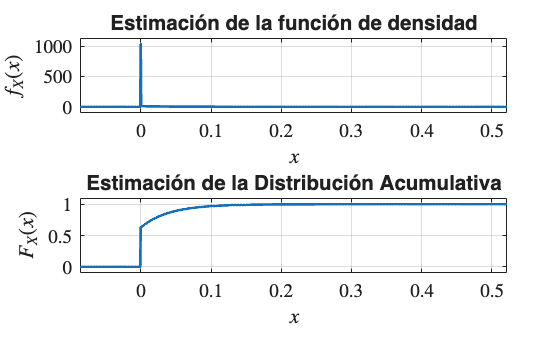

lambda = 15;
mu = 40;
tea = exprnd(1/lambda,1,1000000);
[tw,espera]= xm1(mu,tea);
figure(1);
pdfcdfcontinua(espera);

## Distribución de la media muestral del tiempo de espera.

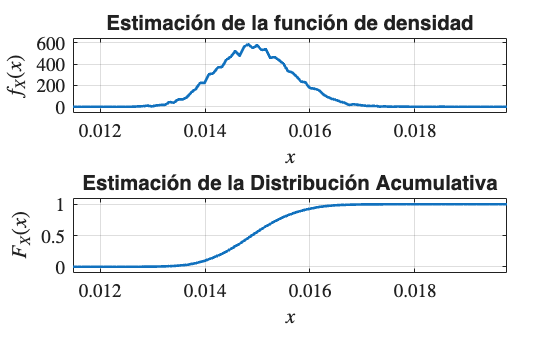

lambda = 15;
mu = 40;

repeticiones = 10000;
datos = zeros(1,repeticiones);

for n = 1:repeticiones
    tea = exprnd(1/lambda,1,10000);
    datos(n) = xm1(mu,tea);
end
figure(2);
pdfcdfcontinua(datos);

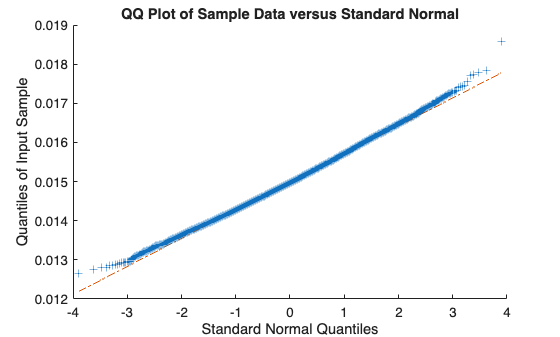

figure(3);
qqplot(datos);

# ¿Tarea?

¿Cómo se puede determinar el intervalo de confianza de un estimador cuando la muestra proviene de una población que no está normalmente distribuída? Proponga un intervalo de confianza adecuado para la función `xm1`, en función de $\lambda/\mu$ y la cantidad de usuarios.

## Ejemplo

Con el siguiente código se puede apreciar que estimar el intervalo de confianza, para datos que no se encuentran normalmente distribuidos, conduce a una confianza diferente a la propuesta (en este ejemplo, la confianza deseada es el 95%).

lambda = 3;
mu = 4;
media = 1/(mu-lambda)-1/mu

media = 0.7500

p = 0;
for n = 1:10000
    tea = exprnd(1/lambda,1,10000);
    [tw,espera]= xm1(mu,tea);
    [MUHAT,SIGMAHAT,MUCI,SIGMACI] = normfit(espera);

    if media>MUCI(1) && media<MUCI(2)
        p = p+1;
    end
end
confianza = p/10000

confianza = 0.2221

# Varianza muestral

El cálculo de los intervalos de confianza requiere del conocimiento de la distribución del estimador que se utilice. Esta, a su vez, depende de la distribución de la muestra y del tamaño de la misma. Por ejemplo, en el caso particular de la media muestral: $\bar{X}$, se sabe que para muestras normalmente distribuídas de tamaño $n$, la distribución de $\bar{X}$ es una normal de media $\mu_{X}$ y desviación $\frac{\sigma_{X}}{\sqrt{n}}$. Esto es:


$$\bar{X} \sim \mathcal{N}\left(\mu_{x},\frac{\sigma_{X}}{\sqrt{n}}\right)$$


De igual manera, si se desea obtener un intervalo de confianza para la varianza, se debe conocer la distribución del estimador respectivo y el tamaño de la muestra. Particularmente, se estudiará la distribución de la varianza muestral: $S^2$, para muestras normalmente distribuídas.

 
$$S^2=\frac{\sum_{i=1}^{n}\left(X_{i}-\bar{X}\right)^2}{n-1}$$


# Distribución chi cuadrado

Dado que el cálculo de la varianza muestral, para muestras normalmente distribuídas, implica obtener el cuadrado de dichas muestras, es conveniente estudiar primero la distribución de la suma de variables aleatorias normal estándar. A tal distribución se le conoce como Chi cuadrado.

## Distribución de $Z^2$

Considérese la variable aleatoria normal estándar:


$$Z \sim \mathcal{N}(0,1)$$


La distribución de la variable aleatoria $Z^2$ es la distribución $\chi^2_1$ (se lee chi cuadrado con un grado de libertad):


$$Z^2 \sim \chi^2_1$$


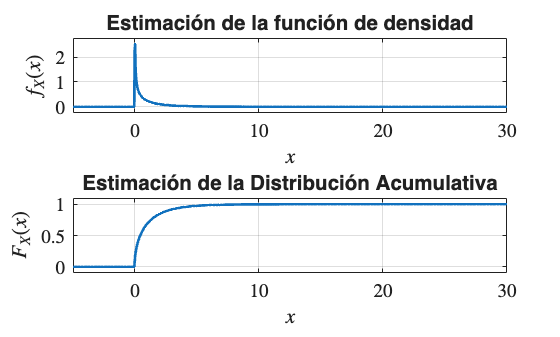

muestra = randn(1,1000000);
datos = muestra.^2;
figure(4);
pdfcdfcontinua(datos);

## Distribución de $\chi^2_n$

Ahora considérese la variable aleatoria normal estándar:


$$Z \sim \mathcal{N}(0,1)$$


La distribución de la variable aleatoria:


$$\sum_{i=1}^{n} Z_i^2$$


es la distribución $\chi^2_n$ (se lee chi cuadrado con $n$ grados de libertad):


$$\chi^2_n$$


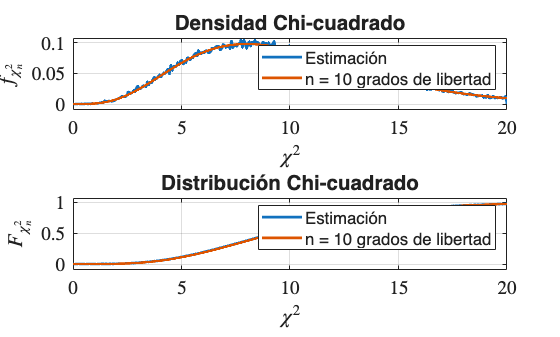

n = 10;
minimo = 0;
maximo = 20;
muestra = randn(n,100000);
if n == 1
    datos = muestra.^2;
else
    datos = sum(muestra.^2);
end
figure(5);
pdfcdfcontinua(datos,minimo,maximo);

x = linspace(minimo,maximo,10000);
pdf = chi2pdf(x,n);
cdf = chi2cdf(x,n);
subplot(2,1,1);
hold on;
superplot(x,pdf,'Densidad Chi-cuadrado',...
    '$\chi^2$','$f_{\chi_{n}^2}$');
hold off;
if n==1
    legend('Estimación','Un grado de libertad');
else
    legend('Estimación',['n = ',...
    num2str(n),' grados de libertad']);
end
subplot(2,1,2);
hold on;
superplot(x,cdf,'Distribución Chi-cuadrado',...
    '$\chi^2$','$F_{\chi_{n}^2}$');
hold off;
if n==1
    legend('Estimación','Un grado de libertad');
else
    legend('Estimación',['n = ',...
    num2str(n),' grados de libertad']);
end

# Estimador de la varianza

La varianza muestral es el estimador:


$$S^2 = \frac{\sum_{i=1}^n(X_i-\bar{X})^2}{n-1}$$


En donde $\bar{X}$ es la media muestral:


$$\bar{X} = \frac{\sum_{i=1}^n X_i}{n}$$


## Estimador de la varianza para datos normalmente distribuidos

Si los valores de una muestra aleatoria están normalmente distribuidos:

$X_i \sim \mathcal{N}\left( \mu_X,\sigma_X \right)$       (1)

entonces, la variable aleatoria $\bar{X}$ se distribuye normal con parámetros $\mu_X$ y $\frac{\sigma_X}{\sqrt{n}}$:


$$\bar{X}  \sim \mathcal{N}\left(\mu_X,\frac{\sigma_X}{\sqrt{n}}\right)$$


y la variable aleatoria $Z$, se distribuye normal estándar:

$Z =\frac{\bar{X}-\mu_X}{\frac{\sigma_X}{\sqrt{n}}} \sim \mathcal{N}(0,1)$      (2)

Ahora, partiendo de la varianza muestral:


$$S^2 = \frac{\sum_{i=1}^n(X_i-\bar{X})^2}{n-1}$$


Se obtiene que:


$$(n-1)S^2 =\sum_{i=1}^n(X_i-\bar{X})^2$$



$$(n-1)S^2 =\sum_{i=1}^n(X_i-\mu_X+\mu_X-\bar{X})^2$$



$$(n-1)S^2 =\sum_{i=1}^n(X_i-\mu_X)^2+
2\sum_{i=1}^n(X_i-\mu_X)(\mu_X-\bar{X})
+\sum_{i=1}^n(\mu_X-\bar{X})^2$$



$$(n-1)S^2 =\sum_{i=1}^n(X_i-\mu_X)^2+
2(\mu_X-\bar{X})(n\bar{X}-n\mu_X)
+n(\mu_X-\bar{X})^2$$



$$(n-1)S^2 =\sum_{i=1}^n(X_i-\mu_X)^2-n(\mu_X-\bar{X})^2$$



$$\frac{(n-1)S^2}{\sigma_X^2} =
\frac{\sum_{i=1}^n(X_i-\mu_X)^2}{\sigma_X^2}
-\frac{n(\mu_X-\bar{X})^2}{\sigma_X^2}$$



$$\frac{(n-1)S^2}{\sigma_X^2} =
\sum_{i=1}^n\left(\frac{X_i-\mu_X}{\sigma_X}\right)^2
-\left(\frac{\bar{X}-\mu_X}{\frac{\sigma_X}{\sqrt{n}}}\right)^2$$


Ahora bien, considerando (1) y (2) se obtiene:

$\frac{(n-1)S^2}{\sigma_X^2} = \sum_{i=1}^n Z_i^2 - Z^2$       (3)

y el resultado mostrado en (3) es la suma de $n-1$ variables aleatorias normal estándar elevadas al cuadrado:


$$\frac{(n-1)S^2}{\sigma_X^2} =
\sum_{i=1}^{n-1}Z_i^2$$


Por lo tanto:


$$\frac{(n-1)S^2}{\sigma_X^2} \sim \chi_{n-1}^2$$


En conclusión, si $S^2$ es la varianza muestral de una muestra aleatoria de tamaño $n$, tomada de una población normalmente distribuida con varianza $\sigma_X^2$, entonces el estadístico o estimador:


$$\frac{(n-1)S^2}{\sigma_X^2} = \sum_{i=1}^n\frac{(X_i-\bar{X})^2}{\sigma_X^2}$$


se distribuye $\chi^2$ con $n-1$ grados de libertad.

## Intervalo de confianza de la desviación estándar

n = 2;
muestra = randn(1,n);
minimo = sqrt((n-1)/chi2inv(0.975,n-1))*std(muestra);
maximo = sqrt((n-1)/chi2inv(0.025,n-1))*std(muestra);
[minimo,maximo]

ans =     0.0024    0.1703


[MUHAT,SIGMAHAT,MUCI,SIGMACI] = normfit(muestra);
SIGMACI

SIGMACI =     0.0024
    0.1703


# Regresión lineal

Considérese un conjunto de $n$ parejas de datos, conformado por las parejas ordenadas $(x_i,y_i)$ con $i=\{1, 2, ..., n\}$. Dicho conjunto se puede representar en el plano cartesiano, tal y como se muestra en el siguiente ejemplo:

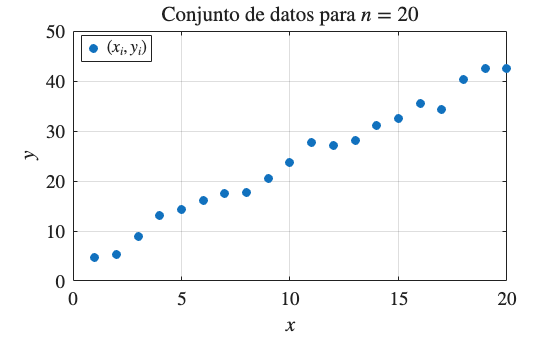

n = 20;% Tamaño del conjunto de datos
x = 1:n;            % vector de x

pendiente = 2;      % Pendiente que se espera estimar
corte = 3;          % Corte con el eje $y$ que se espera estimar

y = pendiente*x + corte + randn(1,n);    % Se adiciona ruido normalmente distribuido

figure(6);
plot(x,y,'.','MarkerSize',20);
set(gca,'FontSize',14);
set(gca,'TickLabelInterpreter','latex');
title({['Conjunto de datos para $n = ',num2str(n),'$']},...
    'Interpreter','latex');
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
grid on;
legend({'$(x_i,y_i)$'},'Interpreter','latex',...
    'Location','best');

Se desea obtener una linea recta que represente al conjunto de datos. La ecuación para dicha recta es:


$$\hat{y}=\hat{m}x+\hat{b}\qquad{(1)}$$


en donde:


$$x = [x_1, x_2, \dots,x_i,\dots, x_n]\qquad{(2)}$$



$$\hat{y} = [\hat{y_1} ,\hat{y_2} , \dots,\hat{y_i} ,\dots, \hat{y_n} ]\qquad{(3)}$$


Con


$$\hat{y_i}=\hat{m}x_i+\hat{b};\qquad{}i=\{1,2,\dots,n\}\qquad{(4)}$$


Nótese que $\hat{m}$ y $\hat{b}$, son los mismos para cada pareja ordenada. En otras palabras, tanto $\hat{m}$ como $\hat{b}$, son parámetros que no dependen de $i$, y sólo se requiere una pareja de estimadores para el conjunto de datos ($\hat{m}$, el estimador de la pendiente; $\hat{b}$, el estimador del corte con el eje $y$). El problema que se desea abordar, por tanto, se reduce a estimar dichos parámetros.

## Suma de los errores al cuadrado: SSE

Ahora bien, de las infinitas posibilidades, se considerará aquella línea recta que minimice la función de error:


$$SSE=\sum_{i=1}^{n}(y_i-\hat{y_i})^2\qquad{(5)}$$


De la función de error propuesta, se destacan las siguientes ventajas:

- El SSE es una función con sólo dos incognitas, $\hat{m}$ y $\hat{b}$: los parámetros que se desean estimar.

- Si se minimiza la función de error, se obtiene una única solución, lo que garantiza que los valores de $\hat{m}$ y $\hat{b}$ son únicos, para cada conjunto de datos estudiado (Analícese aquellos casos en los que los exponentes del error fuesen impares, por ejemplo).

- La derivada de la función de error conduce a una función de primer orden, lo que facilitará posteriormente, la consecución analítica de $\hat{m}$ y $\hat{b}$ (Estudíese el caso, de tomar exponentes del error pares y mayores que dos, o el caso del valor absoluto del error).

Al reemplazar las ecuaciones (1-4) en la ecuación (5), se obtiene:


$$SSE(\hat{m},\hat{b})=\sum_{i=1}^{n}[y_i - (\hat{m}x_i+\hat{b})]^2\qquad{(6)}$$


Para estimar $\hat{m}$ y $\hat{b}$, se calcularán los puntos críticos de la función de error, igualando las derivadas parciales a cero:


$$\frac{\partial{SSE}}{\partial{\hat{m}}}=\sum_{i=1}^{n}-2x_i[y_i - \hat{m}x_i - \hat{b}]\qquad{(7)}$$


 
$$0=\sum_{i=1}^{n}-2x_i[y_i - \hat{m}x_i - \hat{b}]$$



$$0 = -2\sum_{i=1}^{n}x_iy_i+ 2\sum_{i=1}^{n}\hat{m}x_ix_i+ 2\sum_{i=1}^{n}x_i\hat{b} $$


Y dado que tanto $\hat{m}$ como $\hat{b}$, no dependen de $i$:


$$\hat{m}\sum_{i=1}^{n}x_i^2+ \hat{b}\sum_{i=1}^{n}x_i
= \sum_{i=1}^{n}x_iy_i\qquad{(8)}$$


La derivada parcial de la función de error, con respecto a $\hat{b}$ es:


$$\frac{\partial{SSE}}{\partial{\hat{b}}}=\sum_{i=1}^{n}-2[y_i - \hat{m}x_i - \hat{b}]\qquad{(9)}$$



$$0 = -2\sum_{i=1}^{n}y_i+ 2\sum_{i=1}^{n}\hat{m}x_i+ 2\sum_{i=1}^{n}\hat{b} $$



$$\hat{m}\sum_{i=1}^{n}x_i+ \hat{b}n= \sum_{i=1}^{n}y_i\qquad{(10)}$$


Si la ecuación (10) se divide por $n$, aparecen las medias muestrales de los vectores $x$ e $y$:


$$\hat{m}\bar{x} + \hat{b} = \bar{y}\qquad{(11)}$$


Las ecuaciones (8) y (11) conforman el sistema de ecuaciones lineales:


$$\begin{cases}\hat{m}\sum_{i=1}^{n}x_i^2+ \hat{b}\sum_{i=1}^{n}x_i= \sum_{i=1}^{n}x_iy_i&(8)\\\hat{m}\bar{x}+ \hat{b}= \bar{y}&(11)\end{cases}$$


La solución del sistema de ecuaciones, es:


$$\hat{m}=\frac{\sum_{i=1}^{n}x_iy_i - \bar{y}\sum_{i=1}^{n}x_i}{\sum_{i=1}^{n}x_i^2-\bar{x}\sum_{i=1}^{n}x_i}\qquad{(12)}$$



$$\hat{b} = \bar{y}-\hat{m}\bar{x}\qquad{(13)}$$


Nótese que las operaciones indicadas en (12) y (13) se pueden computar en MATLAB de la siguiente forma:

- $\bar{x}$ e $\bar{y}$, se pueden calcular en MATLAB, con la función `mean`*.*

- $\sum_{i=1}^{n}{x_i}$, se puede calcular con la función `sum`.

-  $\sum_{i=1}^{n}{x_iy_i}$, es el producto punto de $x$ con $y$, o bien el producto de los vectores  $x$ e $y^T$.

- De manera similar, $\sum_{i=1}^{n}{x_i^2}$, es el producto de los vectores  $x$ y $x^T$.

Al final del presente documento, se codifican estas operaciones con la función `recta`.

## Ejemplo de la Función Recta

n = 100;             % Tamaño del conjunto de datos
x = 1:n;            % vector de x

pendiente = 2;      % Pendiente que se espera estimar
corte = 3;          % Corte con el eje $y$ que se espera estimar

y = pendiente*x + corte + randn(1,n);    % Se adiciona ruido normalmente distribuido

[m b] = recta(x,y)

m = 1.9969

b = 3.2068

## Gráfica de la Regresión Lineal Simple

n = 20;% Tamaño del conjunto de datos
x = 1:n;            % vector de x

pendiente = 2;% Pendiente que se espera estimar
corte = 3;% Corte con el eje $y$ que se espera estimar

y = pendiente*x + corte + randn(1,n);    % Se adiciona ruido normalmente distribuido

figure(7);
plot(x,y,'.','MarkerSize',20);
set(gca,'TickLabelInterpreter','latex');
title({['Conjunto de datos para $n = ',num2str(n),'$']},...
    'Interpreter','latex');
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
grid on;

[m b] = recta(x,y)

m = 2.0506

b = 2.7540

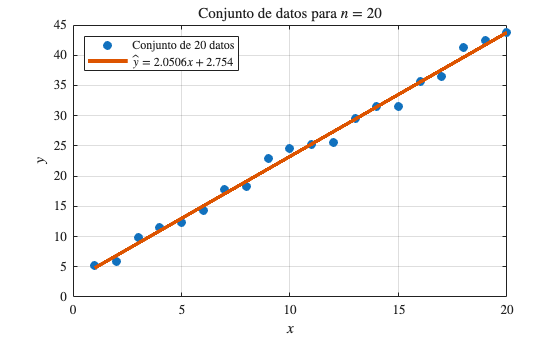

hold on;

t = linspace(1,n,10000);
z = m*t+b;
plot(t,z,'LineWidth',3);

hold off;

legend({['Conjunto de $',num2str(n),'$ datos'],...
    ['$\hat{y} = ',num2str(m),'x + ',num2str(b),'$']},...
    'Location','northwest','Interpreter','latex');

# Dependencia de rango largo (LRD)

Considérese el proceso estocástico de tiempo discreto: $X[k], k \in \mathbb{N}$. En el contexto de una red de comunicaciones, $X[k]$ podría representar el volumen de tráfico en el instante de tiempo $k$, medido en bits, bytes o paquetes; en el contexto financiero, $X[k]$ podría representar los valores de la TRM de cada día; en el contexto geofísico, $X[k]$ podría indicar los niveles de precipitación diarios medidos en una población particular; o bien, en nuestra área de interés, $X[k]$ podría representar la secuencia de tiempos entre picos R, los periodos instantáneos de una señal PPG, el tiempo entre disparos de una neurona motora, etc. En general $X[k]$, es una secuencia discreta que representa los valores de interés, o bajo estudio, de un proceso estocástico en el momento $k$.

Adicionalmente, se define el proceso agregado de $X$, en el nivel de agregación $m$, como la secuencia discreta $X^{(m)}$, conformada por las medias muestrales de los grupos de datos consecutivos, de tamaño $m$. Por ejemplo, si la secuencia discreta está conformada por los siguientes números $X = \{8,2,-3,14,-7,-5,9,6\}$, el proceso agregado de $X$, en el nivel de agregación $2$, es $X^{(2)}=\{0.75,1,0.65,0.95\}$ y el proceso agregado de $X$, en el nivel de agregación $4$, es $X^{(4)}=\{0.875,0.8\}$.


$$X^{(m)}[i]=\frac{1}{m}\sum_{k=m(i-1)+1}^{mi}X[k]$$


x = [2,3,5,235,-4,9,12,7]

x =      2     3     5   235    -4     9    12     7


grupos = reshape(x,2,4)

grupos =      2     5    -4    12
     3   235     9     7


xm = mean(grupos)

xm =     2.5000  120.0000    2.5000    9.5000


grupos = reshape(x,4,2)

grupos =      2    -4
     3     9
     5    12
   235     7


xm = mean(grupos)

xm =    61.2500    6.0000


## Detección de la LRD

Cuando el  proceso $X[k]$ es **exacta** o **asíntóticamente autosimilar**, la varianza muestral del proceso agregado es:


$$S_{X^{(m)}}^2 =\sigma_X^2m^{2H-2},\quad 0.5< H<1 \qquad (1)$$


Cuando $H= 0.5$, los valores de $X$ (o $X^{(m)}$) no estarían correlacionados. Esta situación ocurre en las secuencias discretas de valores independientes, como los vectores aleatorios que se pueden generar con el método de la inversa. El caso: $0.5<H<1$, implica la **dependencia de rango largo (LRD) **(se sugiere revisar el capítulo presentado en [1]).

## Diagrama varianza - tiempo

Si se aplica la función logaritmo en ambos miembros de (1), se obtiene:


$$\log S_{X^{(m)}}^2 =\log \sigma_X^2 + (2H-2)\log m$$


Nótese que la gráfica de $y = \log S_{X^{(m)}}^2$ contra $x=\log m$, es una línea recta de pendiente $2H-2$ y que el parámetro de Hurst se puede estimar por medio de una regresión lineal simple. A dicha gráfica se le conoce en la literatura como el diagrama varianza - tiempo. Para facilitar la estimación de $H$, se ha codificado la función `vt`.

## Ejemplo 1: Tiempos entre arribos de una red de comunicaciones

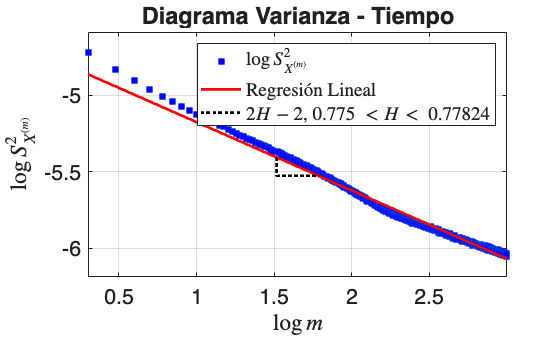

datos = load("BCpAug89.TL");
muestra = diff(datos(:,1)');
figure(8);
vt(muestra);

## Ejemplo 2: Tamaño de los paquetes de una red de comunicaciones

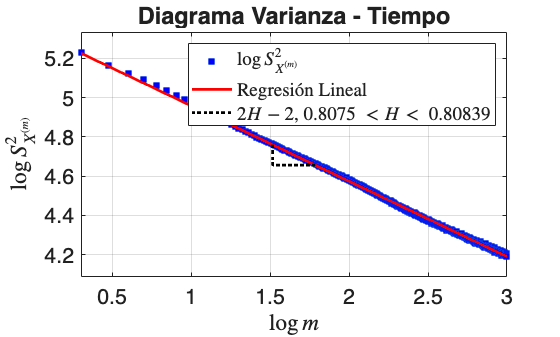

datos = load("BCpAug89.TL");
muestra = datos(:,2)';
figure(9);
vt(muestra);

## Ejemplo 3: Tiempos entre picos R de una señal ECG

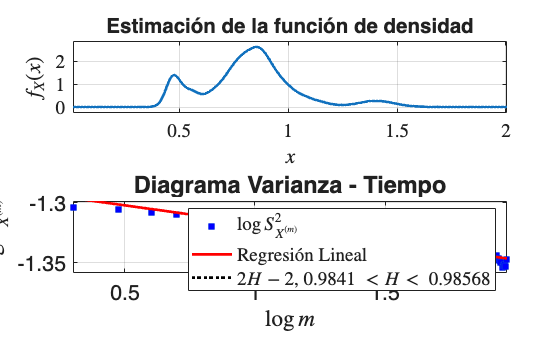

archivo = 'e1301.txt';
muestra = leerrinterval(archivo);
figure(10);
pdfvtcontinua(muestra,0);

## Ejemplo 4: Tiempos entre picos R generados con el método de la inversa

archivo = 'e1301.txt';
tiempos = leerrinterval(archivo);
superfuncion(tiempos);

aleatorio.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: aleatorio(m,n).


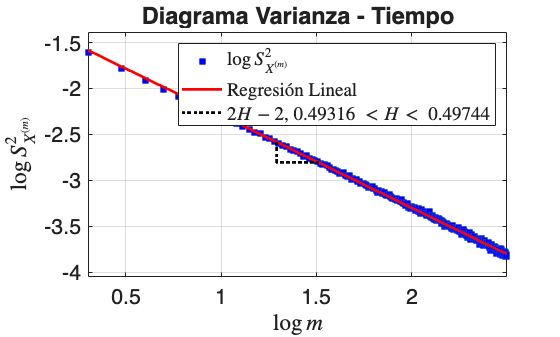

muestra = aleatorio(1,100000);
figure(11);
vt(muestra);

## Ejemplo 5: ¿La TRM tiene LRD?

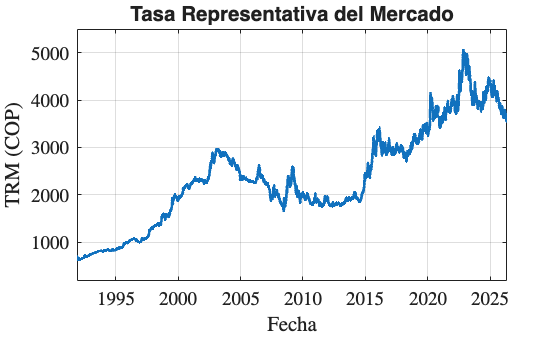

% Archivo descargado de: https://suameca.banrep.gov.co/estadisticas-economicas/informacionSerie/1/tasa_cambio_peso_colombiano_trm_dolar_usd
T = readtable('Tasa de cambio del peso colombiano.xlsx',...
              'VariableNamingRule','preserve');
fecha = datetime(T{:,1}, 'InputFormat','yyyy/MM/dd');
trm   = T{:,2};
idx = ~isnat(fecha) & ~isnan(trm);
fecha = fecha(idx);
trm   = trm(idx);
superplot(fecha, trm, ...
    'Tasa Representativa del Mercado', ...
    '$\textrm{Fecha}$', ...
    '$\textrm{TRM (COP)}$');

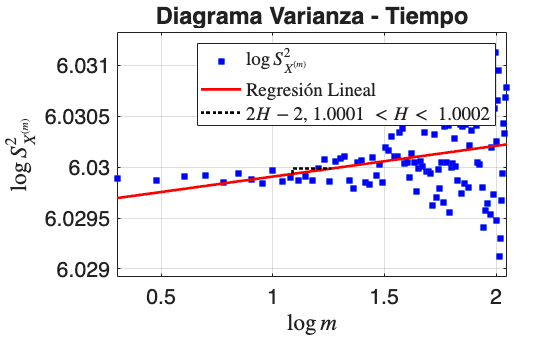

ans = 1.0002

figure(13); 
vt(trm')

## Parámetro H de los incrementos de la TRM

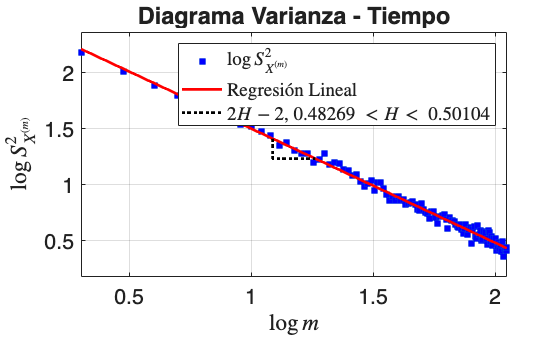

figure(14);
deltatrm = diff(trm');
vt(deltatrm);

# Diagrama Log - Escala

El diagrama varianza tiempo permite estimar el parámetro de Hurst de secuencias discretas aleatorias. No obstante, no es la única herramienta que lo permite hacer. Por ejemplo, el diagrama log - Escala utiliza un estimador basado en los coeficientes de detalle de la transformada wavelet discreta, para estimar `H`.

## Ejemplo 1: Tiempos entre arribos de una red de comunicaciones

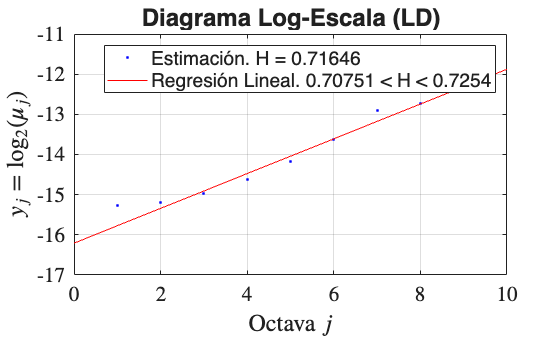

datos = load("BCpAug89.TL");
muestra = diff(datos(:,1)');
figure(15);
LD(muestra);

## Ejemplo 2: Tamaño de los paquetes de una red de comunicaciones

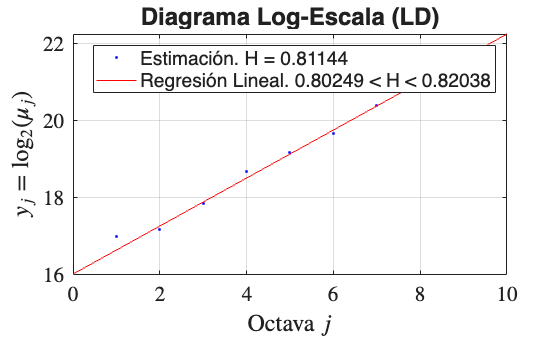

datos = load("BCpAug89.TL");
muestra = datos(:,2)';
figure(16);
LD(muestra);

# Monofractalidad y multifractalidad

La autosimiliud de segundo orden se puede generalizar para los demás momentos estadísticos. De esta manera se podría disponer de un parámetro, para cada momento; y no solo `H`, para el de orden 2. Cuando estos parámetros, denominados exponentes de escala, describen una función lineal de los momentos, a la secuencia discreta se le llama **monofractal**. En caso contrario, se le denomina **multifractal**. La función `dwtleader` de MATLAB permite estimar los parámetros que facilitan la clasificación: una gráfica lineal en los exponentes de escalas indican un comportamiento monofractal; y una gráfica cóncava hacia abajo, en el espectro multifractal, es característica de un comportamiento multifractal.

## Ejemplo 1: Tiempos entre arribos de una red de comunicaciones

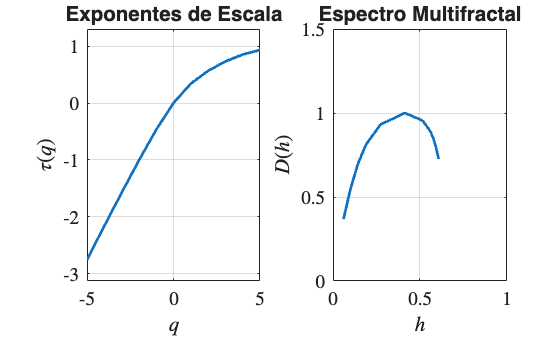

datos = load("BCpAug89.TL");
muestra = diff(datos(:,1)');
[dh,h,cp,tauq] = dwtleader(muestra);
figure(17);
subplot(1,2,1)
superplot(-5:5,tauq,'Exponentes de Escala',...
    '$q$','$\tau(q)$');
subplot(1,2,2)
superplot(h,dh,'Espectro Multifractal',...
    '$h$','$D(h)$');
axis([0 1 0 1.5]);

cp

cp =     0.4130   -0.1358   -0.0553


## Ejemplo 2: Tamaño de los paquetes de una red de comunicaciones

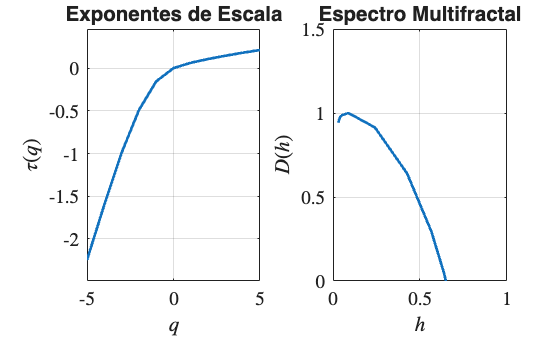

datos = load("BCpAug89.TL");
muestra = datos(:,2)';
[dh,h,cp,tauq] = dwtleader(muestra);
figure(18);
subplot(1,2,1)
superplot(-5:5,tauq,'Exponentes de Escala',...
    '$q$','$\tau(q)$');
subplot(1,2,2)
superplot(h,dh,'Espectro Multifractal',...
    '$h$','$D(h)$');
axis([0 1 0 1.5]);

cp

cp =     0.0888   -0.0851    0.1351


## Ejemplo 3: Tiempos entre picos R de una señal ECG

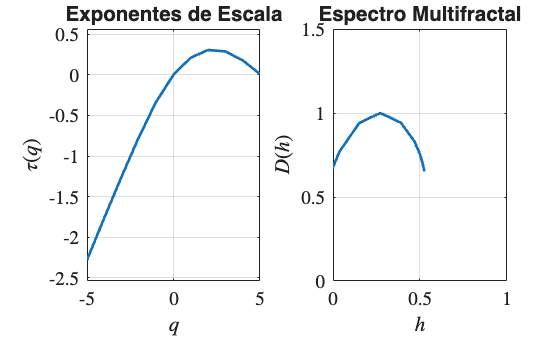

archivo = 'e1301.txt';
muestra = leerrinterval(archivo);
figure(19);
[dh,h,cp,tauq] = dwtleader(muestra);
subplot(1,2,1)
superplot(-5:5,tauq,'Exponentes de Escala',...
    '$q$','$\tau(q)$');
subplot(1,2,2)
superplot(h,dh,'Espectro Multifractal',...
    '$h$','$D(h)$');
axis([0 1 0 1.5]);

cp

cp =     0.2714   -0.1249    0.0038


# Referencias

[1] M. Tuberquia, H. López, and C. Hernández, “Synthesis of Discrete Multifractal Sequences,” en *A Multifractal Model for Cognitive Radio Networks*, 1st ed., Editorial UD, 2019, pp. 89–108.

# Funciones

function [] = areanormalestandar(probabilidad)
    alfa = 1 - probabilidad;
    z1 = norminv(alfa/2,0,1);
    z2 = norminv(1-alfa/2,0,1);
    z = linspace(-4,4,10000);
    intervalo = linspace(z1,z2,10000);
    pdf = normpdf(z,0,1);
    
    if z2 > 4
        intervalo = z;
    end
    
    areapdf = normpdf(intervalo,0,1);
    
    superplot(z,pdf,'','$z$','$f_Z(z)$');
    title(['$P[$',num2str(z1),'$<Z<$',num2str(z2),'$]$',' = ',...
        num2str(probabilidad)],'Interpreter','latex');
    hold on;
    area(intervalo,areapdf);
    hold off;
    grid off;
    set(gca,'XTick',[z1,z2]);
    if probabilidad < 0.4
        set(gca,'XTickLabel',['','']);
        text(z2,0.02,['$\leftarrow z_2 = $',num2str(z2)],...
            'Interpreter','latex','Fontsize',14);
        text(z1,-0.02,['$\leftarrow z_1 = $',num2str(z1)],...
            'Interpreter','latex','Fontsize',14);        
    end
    legend({'Normal Estándar',['Área = ',...
        num2str(probabilidad)]});
end

function [m,b] = recta(x,y)
    x = x(:)';
    y = y(:)';
    m = (x*y'- mean(y)*sum(x))/...
        (x*x' - mean(x)*sum(x));
    b = mean(y)- m*mean(x);
end